**Haarwavelet transform with wavelet function**

t=1:512;
s=50*sin(t/10)+0.005*(t-256).^2;
subplot(2,1,1);
plot(t,s); axis tight
dwtmode('per');

                                         
*****************************************
**  DWT Extension Mode: Periodization  **
*****************************************
                                         


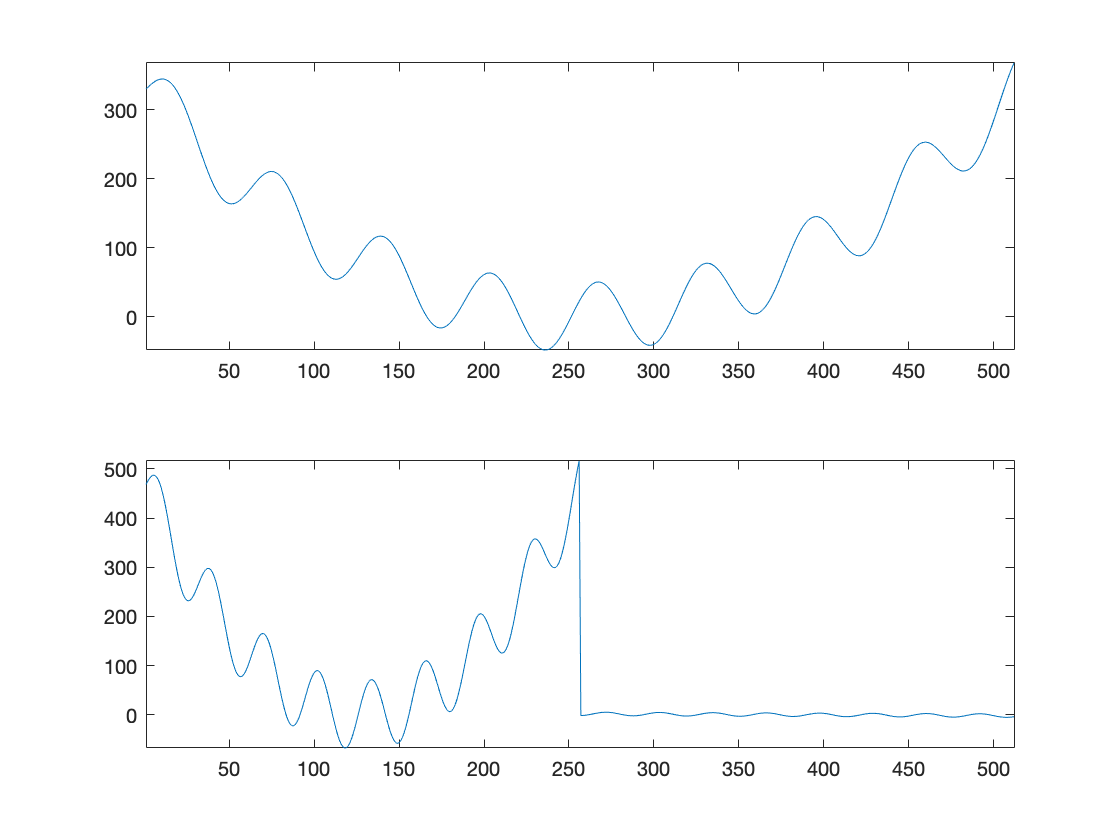

[cA,cD] = dwt(s,'haar');
subplot(2,1,2);
plot(t,[cA cD]);axis tight

Question 4.1

%x = [1, 4, 2, 3, 1, 0, 0, 2];
x=1:17640

x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


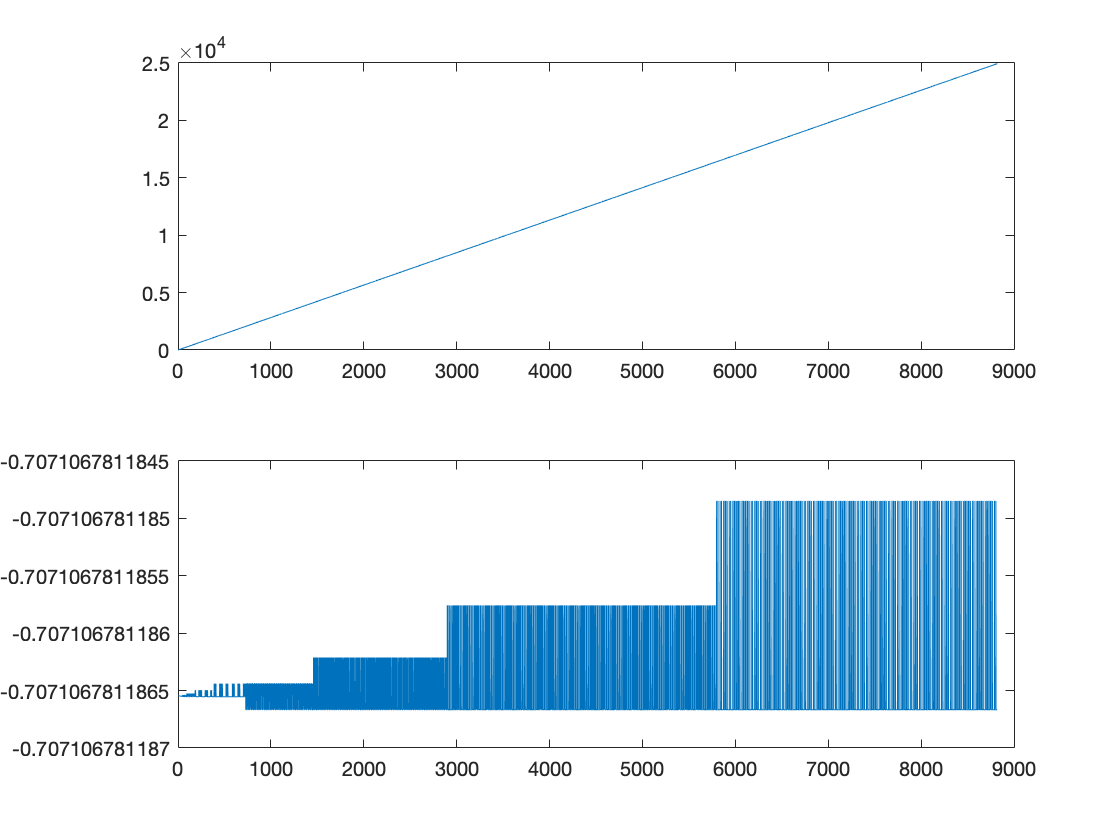

c=[1/sqrt(2),1/sqrt(2)];
d=[-1/sqrt(2),1/sqrt(2)];

[a,b]=dwlt(x,c,d);

t = 1:length(a);

figure;
subplot(211);
plot(t,a)

subplot(212);
plot(t,b)


energy_cons=sum(x.^2)

energy_cons = 1.8298e+12

energy_coef=sum(a.^2)+sum(b.^2)

energy_coef = 1.8298e+12


X=idwlt(a,b,c,d)

X = 	1.0e+04 *

    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049    0.0050


Question 4.2

clear
% a=filter(h_0)
% a(2:2:end)
% 
% a_u=kron(a_d,[1,0])
% b_u
% 
% a_r=filter([1 1],1,a_u)
% a_r=filter([1 -1],1,a_u)
% a_r+b_r

x = [1, 4, 2, 3, 1, 0, 0, 2];

c=[1/sqrt(2),1/sqrt(2)];
d=[-1/sqrt(2),1/sqrt(2)];

%[c,l] = wavedec(x,5,'db1')

wav=wldecom(x,4,c,d)

wav =     4.5962    2.4749         0   -0.5000   -2.1213   -0.7071    0.7071   -1.4142


Question 4.4

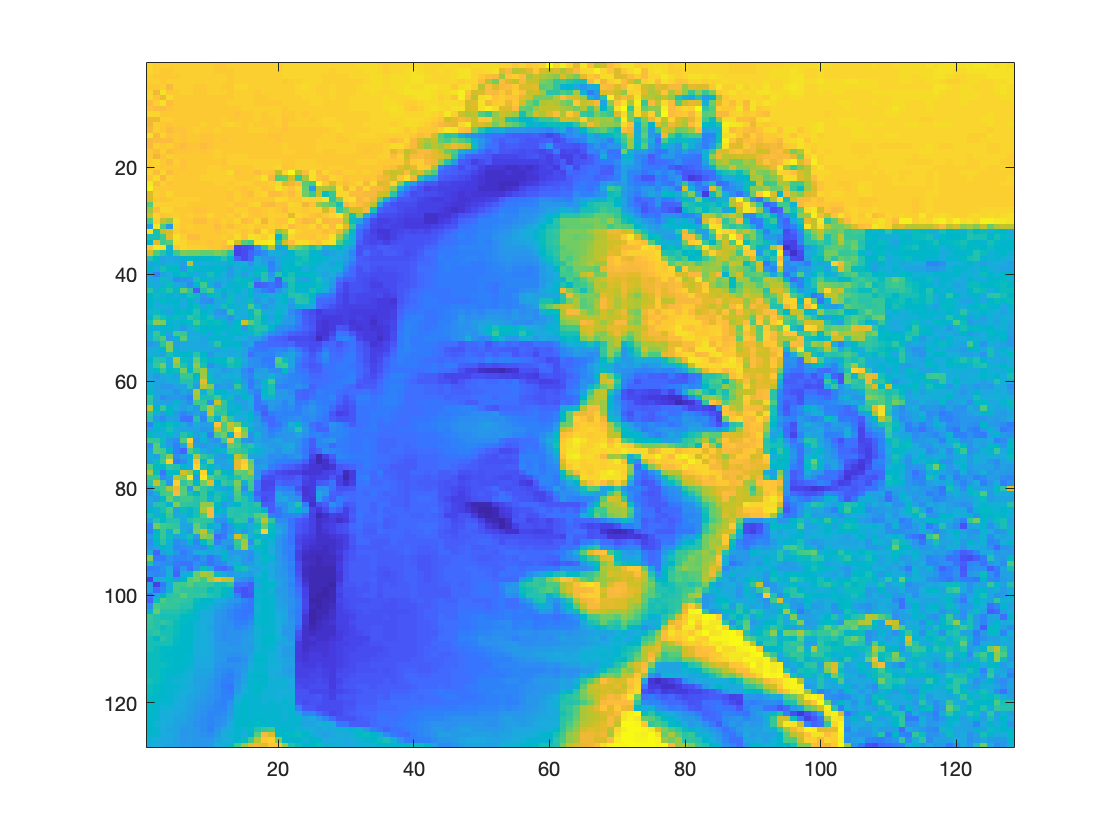

clear

load('ronald.mat');

c=[1/sqrt(2),1/sqrt(2)];
d=[-1/sqrt(2),1/sqrt(2)];

figure;
imagesc(ronald)

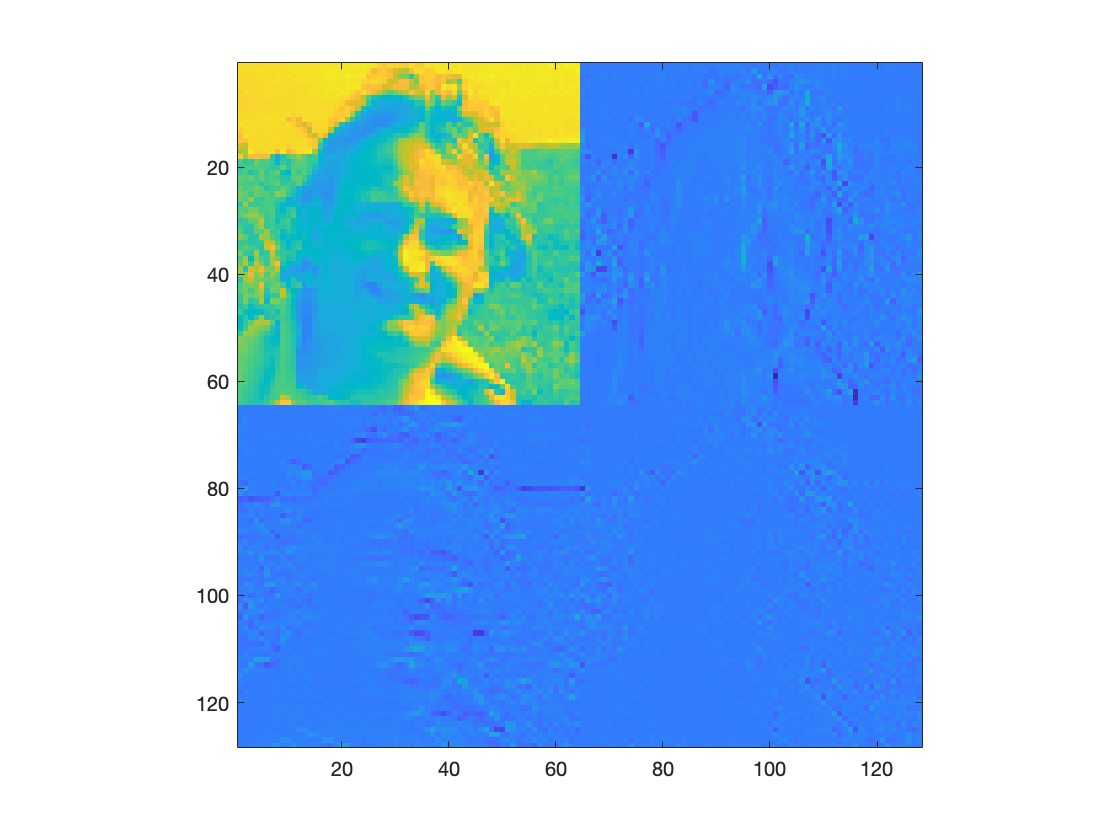


% Obtain the 2-D Haar transform
[a,h,v,dd]=haart2(ronald,1);
figure
imagesc([a v;h dd]);
axis image

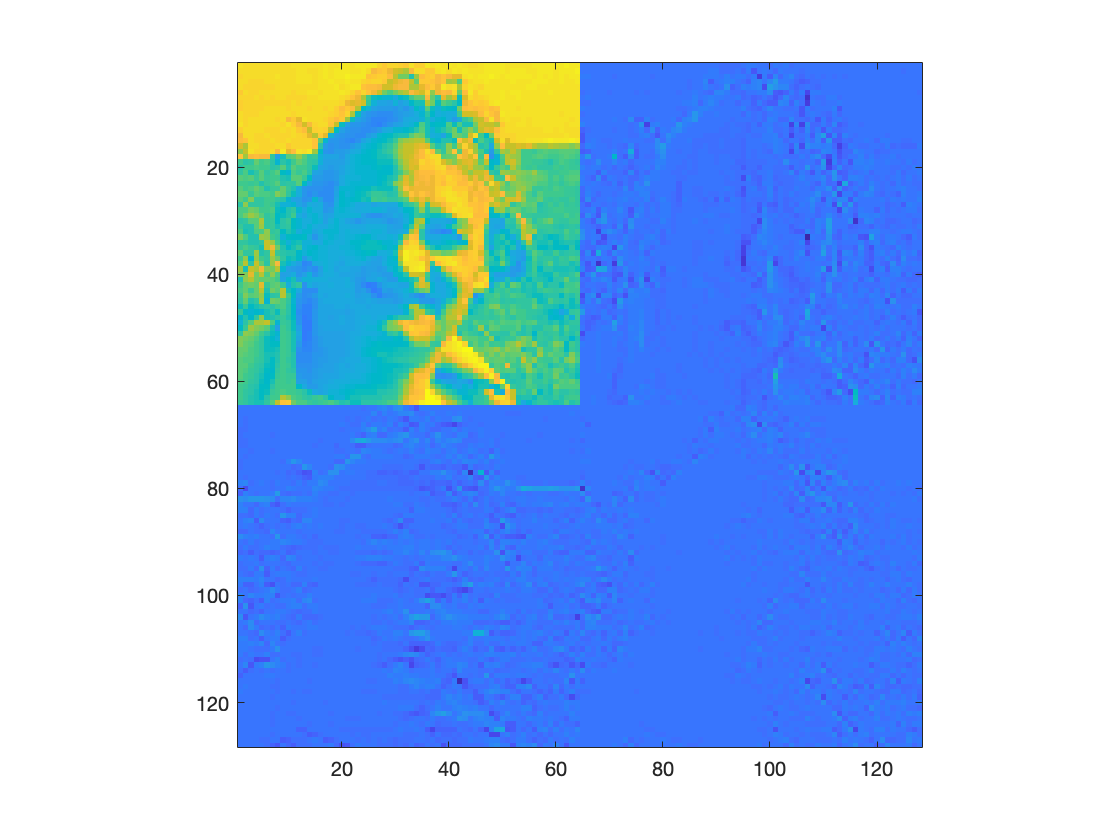



%%
[b1, h1, v1, d1]=dwlt2(ronald,c,d);
figure
imagesc([b1 v1;h1 d1]);
axis image


% 
% colormap gray



Question 4.5

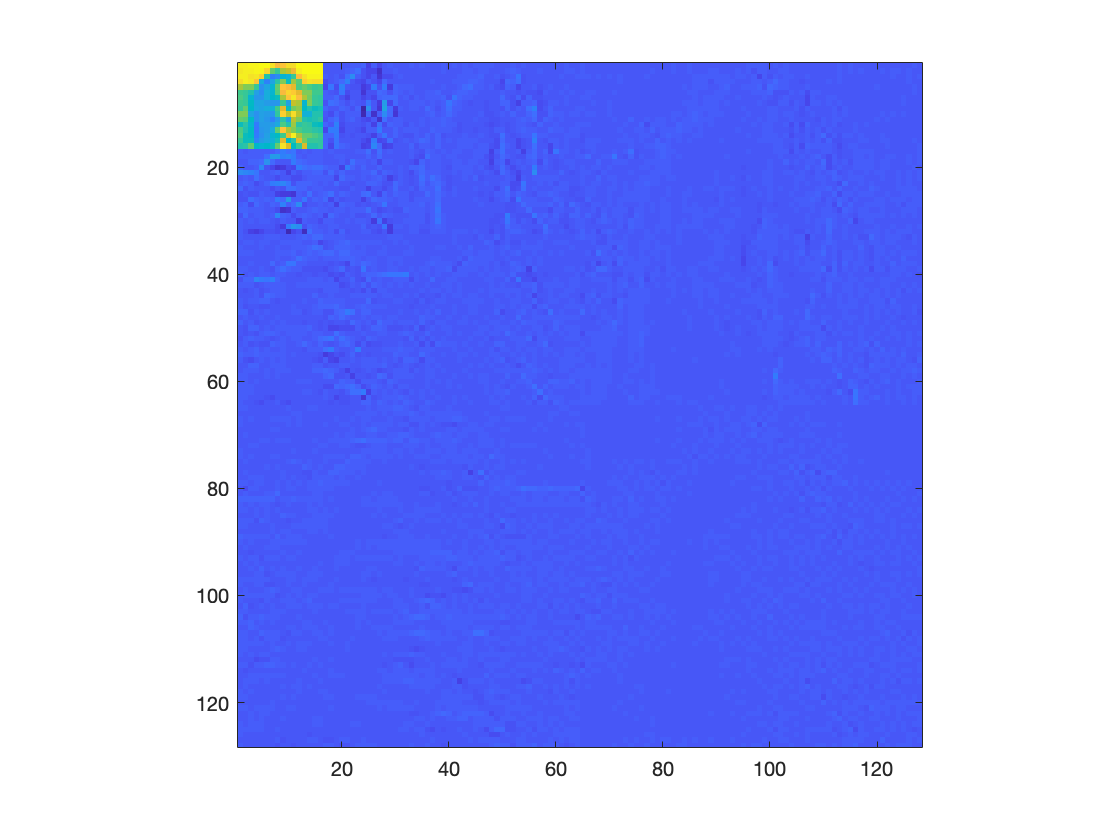

[b1,h1,v1,d1]=dwlt2(ronald,c,d);
[b2,h2,v2,d2]=dwlt2(b1,c,d);
[b3,h3,v3,d3]=dwlt2(b2,c,d);

figure;
imagesc([[[b3 v3;h3 d3] v2; h2 d2] v1;h1 d1]);
axis image

Question 4.6

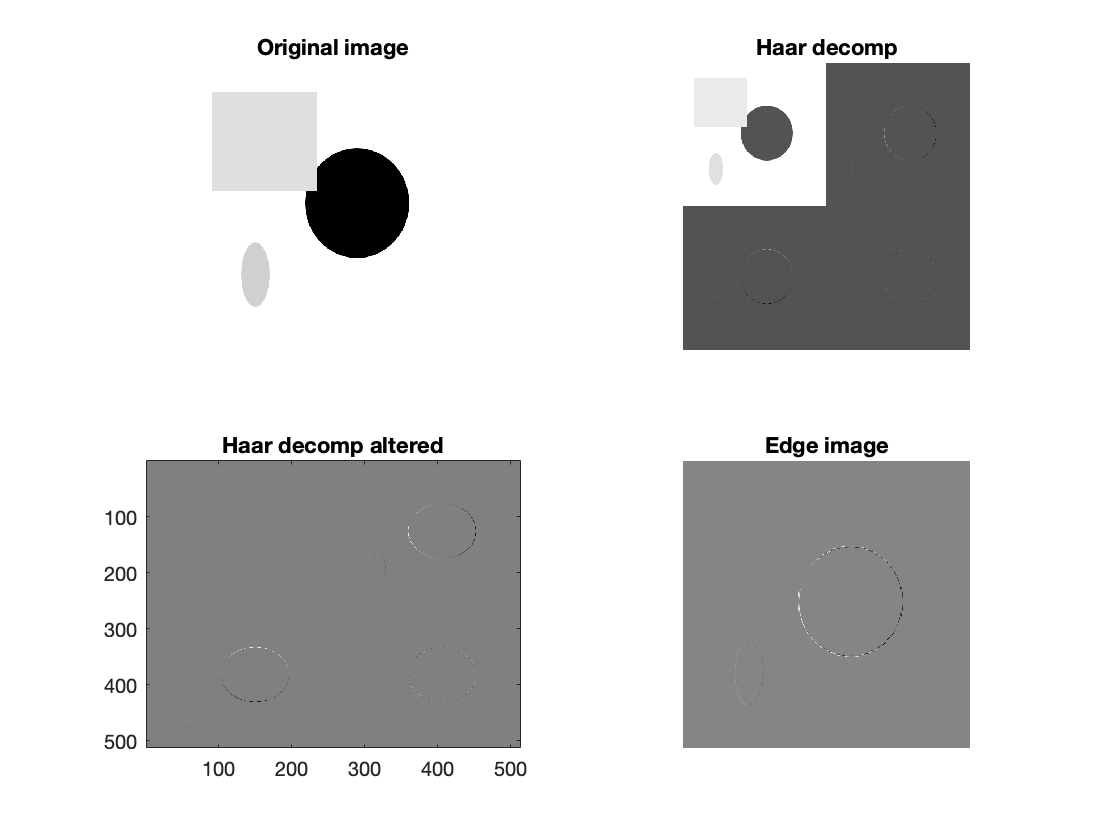

clear

foo=imread('foo.png');

c=[1/sqrt(2),1/sqrt(2)];
d=[-1/sqrt(2),1/sqrt(2)];

[b1,h1,v1,d1]=dwlt2(foo,c,d);

bs=zeros(size(b1));

R=idwlt2(bs,h1,v1,d1,c,d);
figure;
subplot(2,2,1);
image(foo);
axis image off
colormap(gray(256));
title('Original image')
subplot(2,2,2);
imagesc([b1 v1;h1 d1]);
axis image off
title('Haar decomp')
subplot(2,2,3);
imagesc([bs v1;h1 d1]);
title('Haar decomp altered')
subplot(2,2,4);
imagesc(R)
axis image off
title('Edge image')

Question 7

alfa=1.0;
% S=abs([v1(:);h1(:);d1(:)]);
% stop=false;
% tau=(min(S)*max(S))/2;
% while(-stop)
%     S1=S(S<tau);
%     S2=S(S>=tau);
%     tau_new=(mean(S1)+mean(S2))/2;
%     if (abs(tau_new-tau)<alfa)
%         stop=true;
%     end
%     tau=tau_new;
% end

tau=thresholding(alfa,h1,v1,d1)

tau = 0

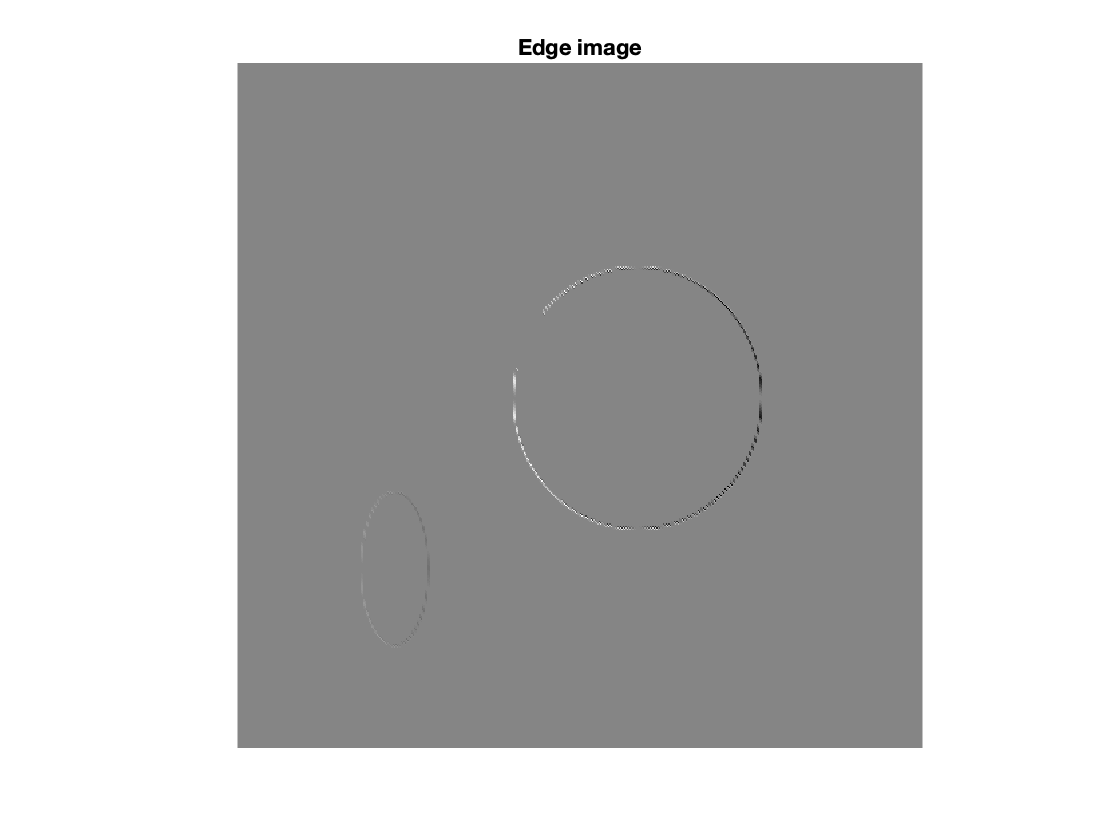


R=idwlt2(bs,h1.*(abs(h1)>tau),v1.*(abs(v1)>tau),d1.*(abs(d1)>tau),c,d);
figure;
imagesc(R);
colormap gray
axis image off
title ('Edge image')

Question 8

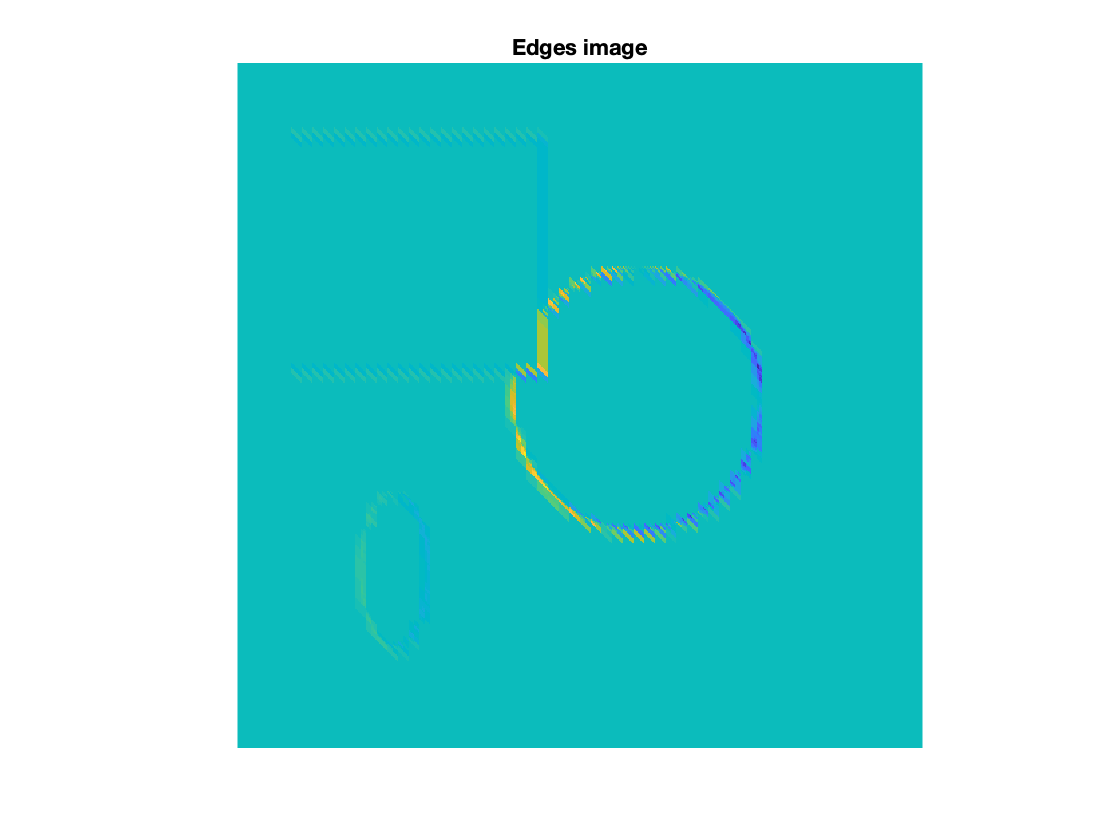

[b1,h1,v1,d1]=dwlt2(foo,c,d);
[b2,h2,v2,d2]=dwlt2(b1,c,d);
[b3,h3,v3,d3]=dwlt2(b2,c,d);

bs3=zeros(size(b3));
bs2=idwlt2(bs3,h3,v3,d3,c,d);
bs1=idwlt2(bs2,h2,v2,d2,c,d);

R=idwlt2(bs1,h1,v1,d1,c,d);

figure;
imagesc(R);
axis image off
title('Edges image')

Question 9

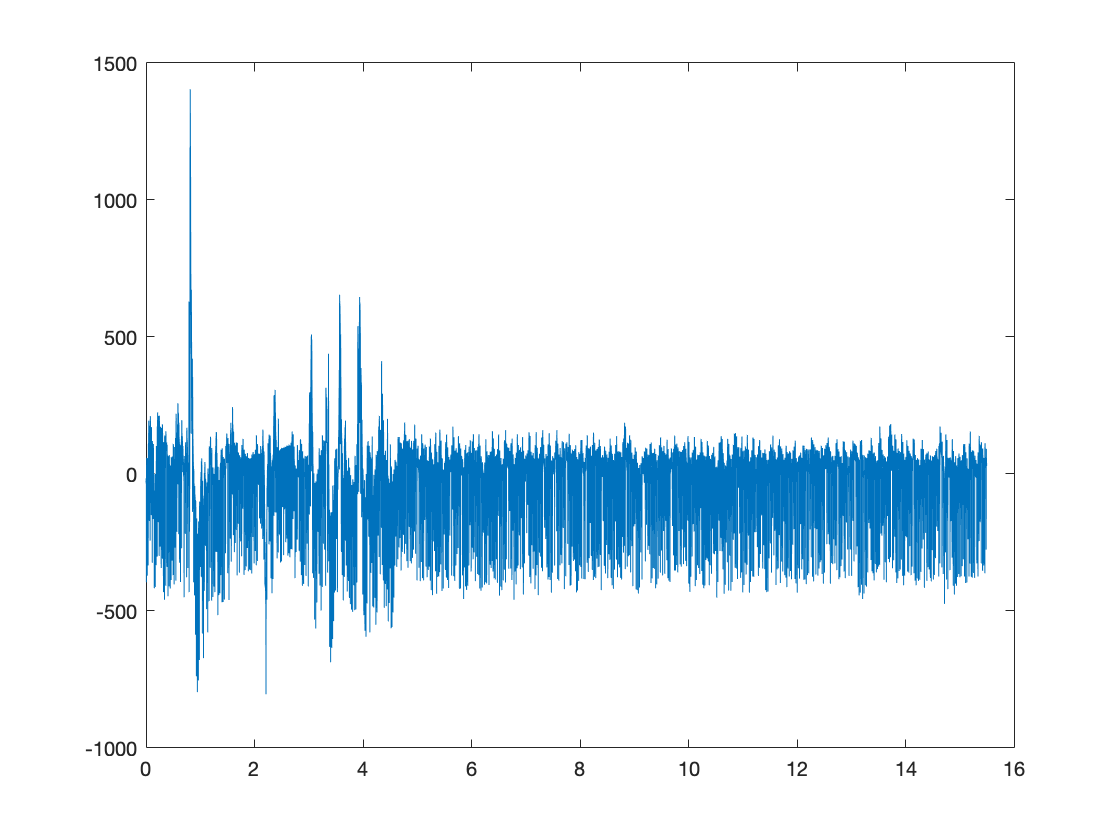

clear
load('data2_1.mat')

fs=15.5;
Nx = length(x);
window = 64;
noverlap = 60;
Ts=1/fs;
t=0:Ts:10;

x1=fft(x);

% Define the frequencies
f=linspace(0,fs,length(x1)+1);
f(end)=[];

%hamming window function
figure
plot(f,x)

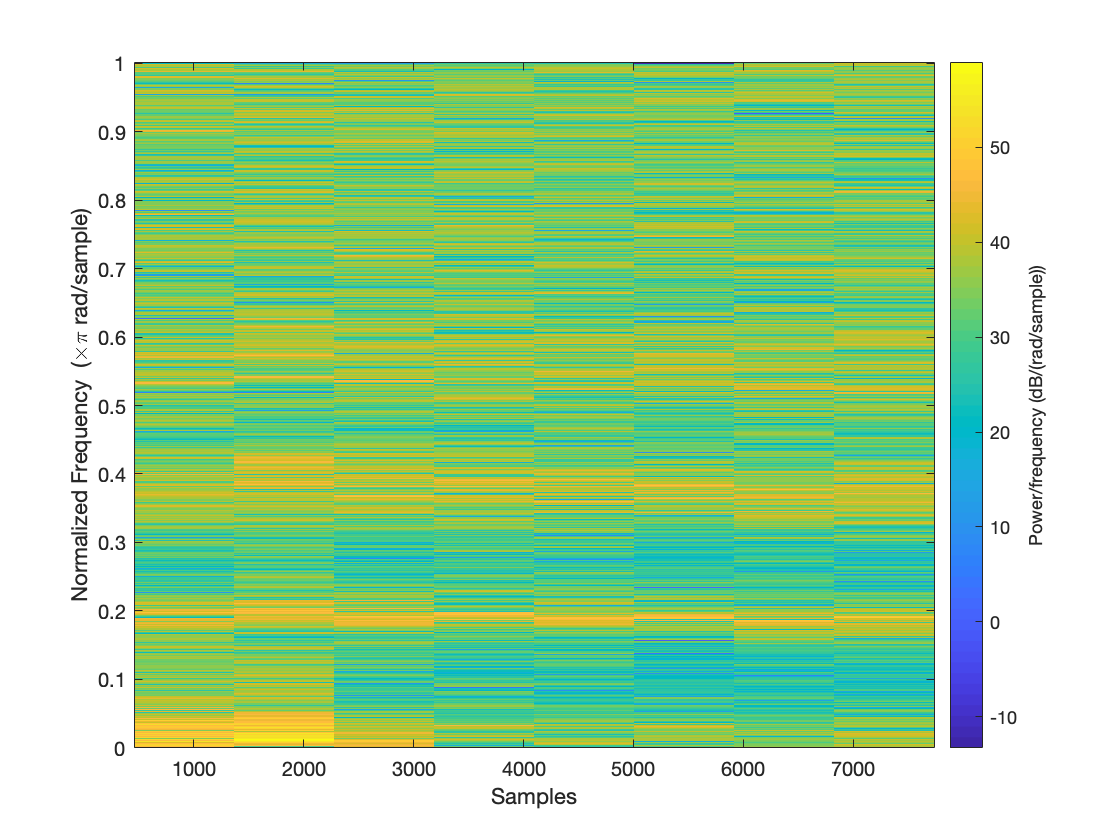

%axis([0,10,-1000,1500])
figure
spectrogram(x,'yaxis')

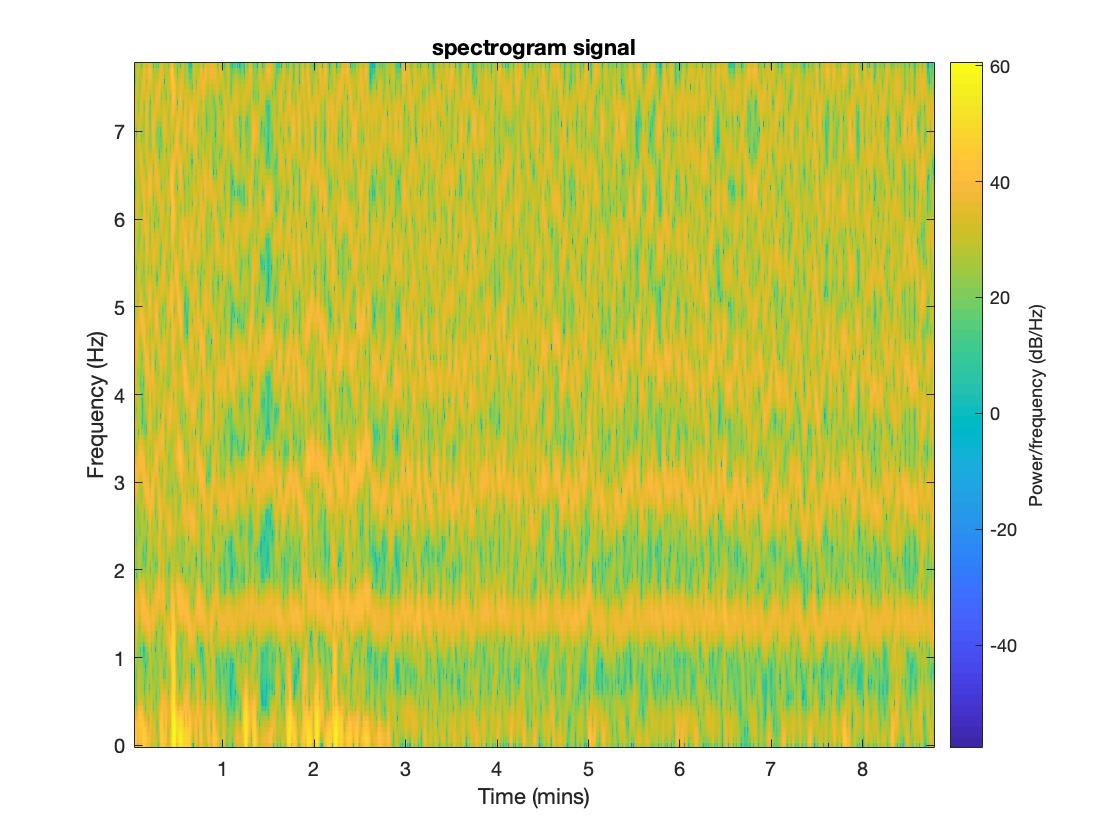

figure
spectrogram(x,window,noverlap,[],fs,'yaxis');
title('spectrogram signal')

% figure
% spectrogram(x,hamming(window),noverlap,[],fs,'yaxis');
% title('spectrogram signal')
t=((1:length(x))/(fs*60));
figure
a1=subplot(211)

a1 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.5838 0.7750 0.3412]
            Units: 'normalized'

  Show all properties


plot(t,x);
a2=subplot(212)

a2 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.3412]
            Units: 'normalized'

  Show all properties


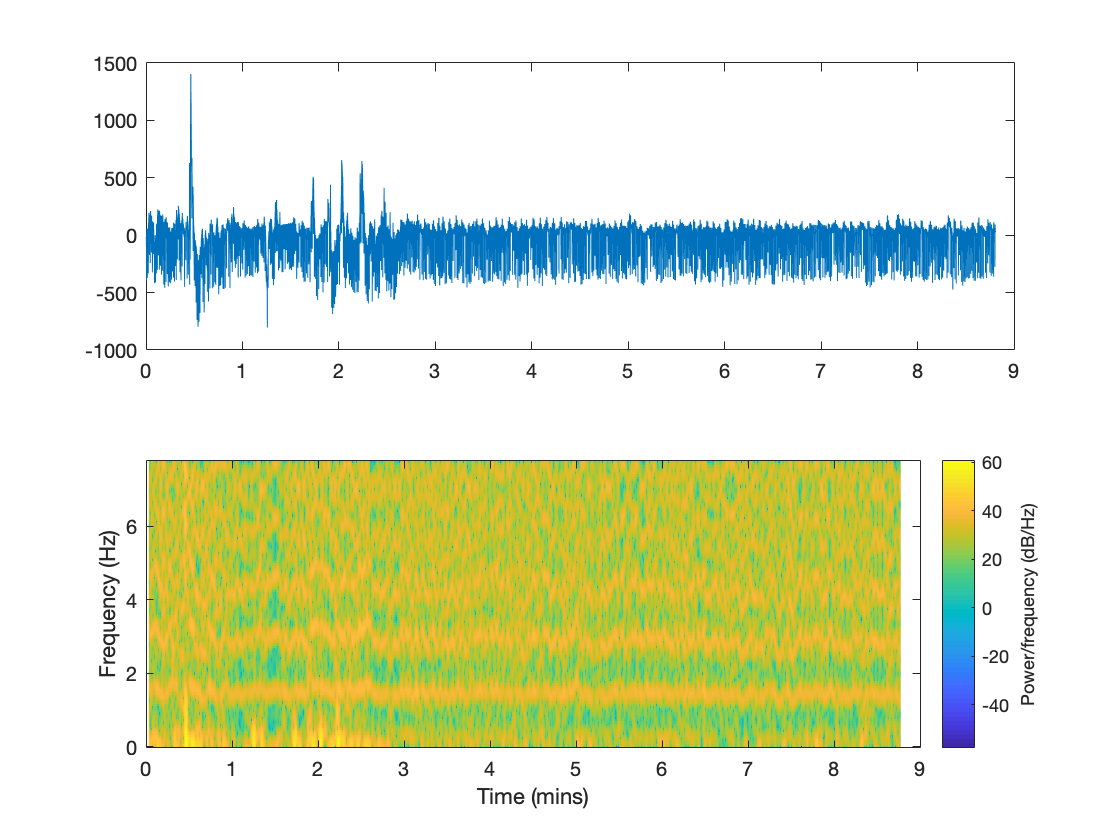

spectrogram(x,window,noverlap,[],fs,'yaxis');
linkaxes([a1, a2],'x');



% plot the fft

% figure(2);
% 
% subplot(2,1,1);
% 
% plot(f,abs(x1));title('magnitude spectrum signal');xlabel('frequency (Hz)')
% 
% subplot(2,1,2);
% 
% plot(f,angle(x1));title('phase spectrum signal');xlabel('frequency (Hz)')
% 
%  
% 
% %% Effect of nonstationarity signal 1

% When we zoom in on the frequency band of interest we see some strange

% behavior

% figure(3);
% 
% plot(f,abs(x1));
% axis([0,50,0,300]);
% title('magnitude spectrum signal zoomed');xlabel('frequency (Hz)')

